# Midterm November 29, 2019

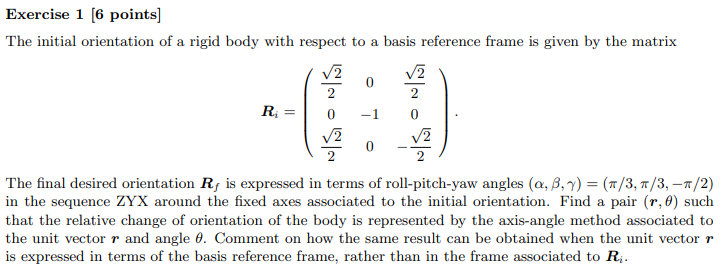

% syms alpha beta gamma
% [Rx Ry Rz] = getEulerRotationMatrices([gamma, beta,alpha ])
% 
% % Eugler angle matrices are multipled in forward order.
% % Not reversed, like roll-pitch-yaw angles
% 
% RZYX = Rx*Ry*Rz

% [R_total, R_set] = getRotMatProduct('ZYX',1,[alpha, beta, gamma])

% angles = [pi/3, pi/3, -pi/2]
% % substitute the value of the angles
% i_R_f = subs(R_total,[alpha, beta, gamma], angles)
% determinant = simplify(det(i_R_f))

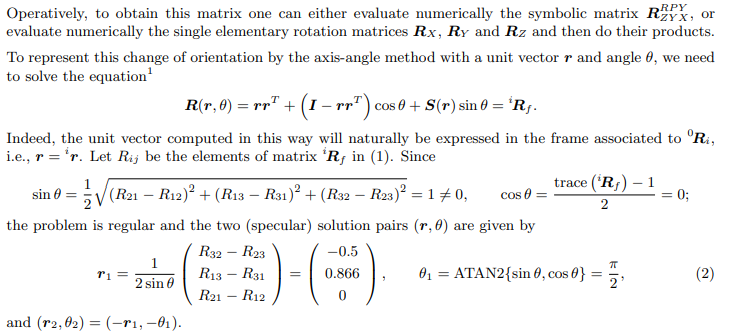

% r=sym('r',[3,1])
% angle=sym('theta')
% A_=[sqrt(1/2),0,sqrt(1/2);
%     0,-1,0;
%     sqrt(1/2),0,-sqrt(1/2)]
% R_0_i=A_
% A_R_B=simplify(getRotAroundVector(r,angle))
% R_r_theta_=solve(A_R_B==i_R_f)
% r_1=[ R_r_theta_.r1, R_r_theta_.r2, R_r_theta_.r3]%, R_r_theta_.theta]% it is also rf?
% r1=vpa(r_1)' %r in the end efector
% 

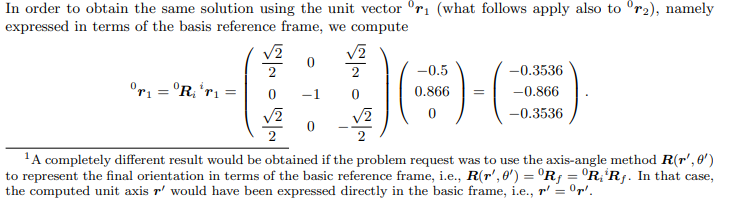.

% r_0_1=vpa(R_0_i*(r1(:,2)))

## 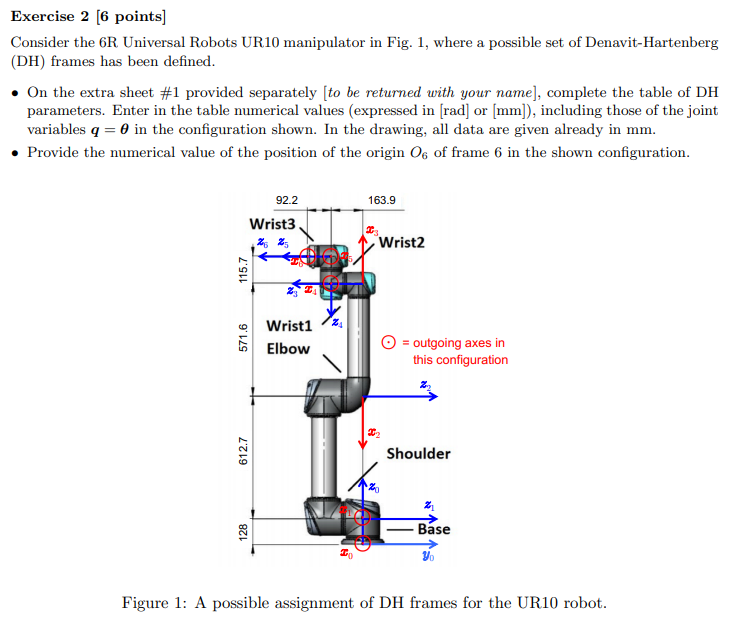

% % clear all, 
% close all, clc
% syms A B C D q1 q2
% Njoints=6;
% q=sym('q',[Njoints,1]);
% L_=3
% d1_=1;
% d2_=1;
% syms alpha beta gamma L
% 
% a1=A
% a2=6
% dhTable=[-pi/2,0,128,q(1);
%          0,-612.7,0,q(2);
%          pi,571.6,0,q(3);
%          pi/2,0,163.9,q(4);
%          -pi/2,0,-115.7,q(5);
%          0,0,92.2,q(6)
%          ];
% links = [
%     Revolute('alpha', -pi/2,'a', 0,'d', 128)
% %     Prismatic('qlim', [0 5],'alpha',-pi/2,'theta',0);
%     Revolute('alpha', 0,      'a', -612.7,'d', 0);
%     Revolute('alpha', pi,      'a', 571.6,'d', 0);
%     Revolute('alpha',  pi/2,   'a', 0,'d', 163.9);
%     Revolute('alpha', -pi/2,   'a', 0,'d', -115.7);
%      Revolute('alpha',  0,      'a', 0,'d', 92.2);
% 
%     ];
% c600 = SerialLink(links);
% c600.teach([0,pi/2,pi,-pi/2,0,0],'view','y')
% [T_total T_Partial,RTotal,RPartial,PTotal, PPartial] = getTransformationMatrix(dhTable, 'alpha')
% sincos =getShortNotation_SinCos(6)
% digits(4)
% toShortNotation(vpa(T_total),sincos)
% sincos =getShortNotation_SinCos(6)
% digits(4)
% toShortNotation(vpa(PTotal),sincos)
% q_=[0,pi/2,pi,-pi/2,0,0]'
% 
% vpa(subs(PTotal,q,q_))

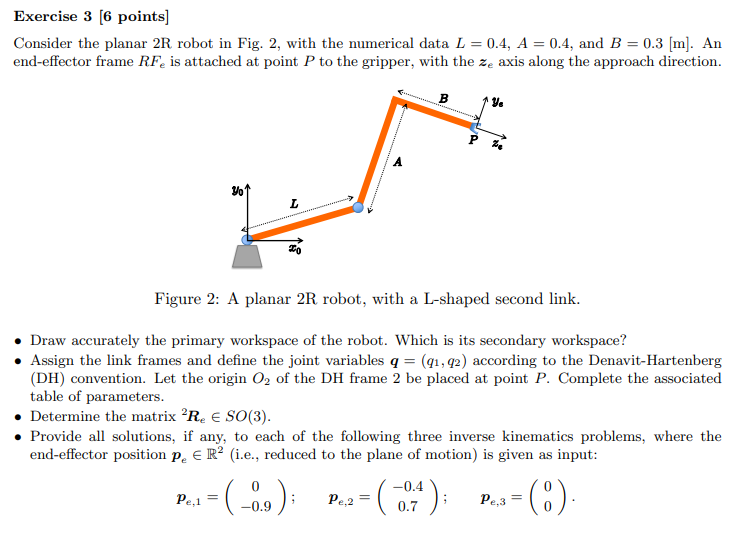

clear all, close all, clc
syms A B C D q1 q2 L
L_=0.4;
B_=0.3;
A_=0.4;
D_=sqrt(B_^2+A_^2);
alpha=sym('alpha', 'real')

$$alpha = \alpha$$

beta=sym('beta', 'real')

$$beta = \beta$$

gamma=sym('gamma', 'real')

$$gamma = \gamma$$

[Rx Ry Rz] = getEulerRotationMatrices()

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} \cos\left(\mathrm{gama}\right) & -\sin\left(\mathrm{gama}\right) & 0\\ \sin\left(\mathrm{gama}\right) & \cos\left(\mathrm{gama}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


[Rz, R_set] = getRotMatProduct('YX',0,[ pi/2,beta])

$$Rz = \left(\begin{array}{ccc} 0 & \sin\left(\beta \right) & \cos\left(\beta \right)\\ 0 & \cos\left(\beta \right) & -\sin\left(\beta \right)\\ -1 & 0 & 0 \end{array}\right)$$

R_set = 2×1 cell array
    {3×3 sym}
    {3×3 sym}


a1=A

$$a1 = A$$

a2=6

a2 = 6

dhTable=[0,L,0,q1;
         0,D,0,q2];
% % De Luca's approach
% links = [
%     Revolute('alpha', 0, 'a', L_ ,'d', 0);
%     Revolute('alpha',  0, 'a', D_,'d', 0)
% 
%     ];
% c600 = SerialLink(links);
% c600.teach([0 0],'view','x')
[T_total T_Partial R_total R_Partial P_total P_Partial] = getTransformationMatrix(dhTable, 'alpha');
T_total %without translation

$$T\_total = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Az=[[Rz 0]',0]';
Az(end,end)=1;
T_total=simplify(T_total*Az)% with beta translation

$$T\_total = \left(\begin{array}{cccc} 0 & -\sin\left(q_{1}-\beta +q_{2}\right) & \cos\left(q_{1}-\beta +q_{2}\right) & \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ 0 & \cos\left(q_{1}-\beta +q_{2}\right) & \sin\left(q_{1}-\beta +q_{2}\right) & \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%R_total=simplify(R_total*Rz)

p_e=T_total(1:3,4)

$$p\_e = \left(\begin{array}{c} \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

p_e2=simplify(P_Partial{1}+R_Partial{1}*P_Partial{2})

$$p\_e2 = \left(\begin{array}{c} \text{D}\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ \text{D}\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

syms px real
syms py real

pehat=[px py]'
q_=solve(p_e2(1:2)==pehat)
pehat_=[0 0]'% case 0 0 the robot is not able to reach this point
parametershat=[pehat;L;D]
parametershat_=[pehat_;L_;D_]

q=vpa([subs(q_.q1,parametershat,parametershat_),subs(q_.q2,parametershat,parametershat_)])';
q=vpa(q*180/pi)
vpa(subs(q_.q2,parametershat,parametershat_))

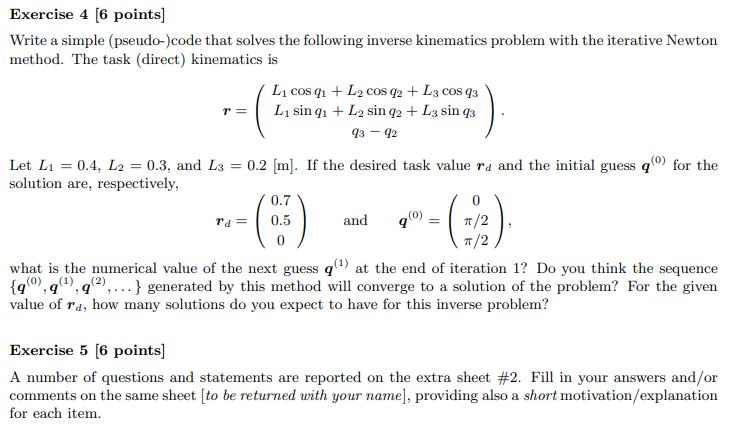

%Newton method
close all, clear all, clc
N=3
Nl=10;
r = sym('r',[N,1],'real');
q = sym('q',[N,1],'real');
L = sym('L',[N,1],'real');
i=1;
r=[(L(1)*cos(q(1))+L(2)*cos(q(2))+L(3)*cos(q(3)));
    (L(1)*sin(q(1))+L(2)*sin(q(2))+L(3)*sin(q(3)));
    q(3)-q(2)];
L_=[0.4;0.3;0.2];
r=vpa(subs(r,L,L_));
 r_N(:,i)=r;
 rd=[0.7;0.5;0];
q_N(:,i)=q;
q_=[0;pi/2;pi/2];
q_N_(:,i)=q_;
r_N_(:,i)=subs(r_N,q,q_);
 J_q=jacobian(r,q)
 
% J_q_N(:,:,i)=subs(J_q,q,q_N(:,i));
% J_q_N_=subs(J_q_N,q,q_N_(:,i));
% q_N(:,i+1)=vpa(q_N(:,i)+inv(J_q_N(:,:,i))*(rd-(r_N(:,i))));%non symbolic
% q_N_(:,i+1)=vpa(subs(q_N(:,i+1),q,q_))
for i=1:Nl
   e(:,i)=rd-r_N_(:,i)
   
   if norm(e(:,i))<0.00001
       i=i-1;
       return;
   end
%     q_N(:,i)=q;
%     q_=[0;pi/2;pi/2];
%     q_N_(:,i)=q_;
%     J_q_N(:,:,i)=subs(J_q,q,q_N(:,i));
    J_q_N_=subs(J_q,q,q_N_(:,i));
    Inv_J_q_N=inv(J_q_N_);
%     q_N(:,i+1)=vpa(q_N(:,i)+(inv(J_q_N(:,:,i)))*(rd-(r_N(:,i))));%non symbolic
    digits(5)
    q_N_(:,i+1)=vpa(q_N_(:,i)+(Inv_J_q_N)*(rd-(r_N_(:,i))))%non symbolic
    r_N(:,i+1)=r;
%     q_N_(:,i+1)=vpa(subs(q_N(:,i+1),q,q_N_(:,i)))
    r_N_(:,i+1)=vpa(subs(r_N(:,i+1),q,q_N_(:,i+1)))
    

    
end

q_N_ =          0         0
    1.5708    0.9708
    1.5708    0.9708


$$r\_N\_ = \left(\begin{array}{cc} 0.4 & 0.68232\\ 0.5 & 0.41267\\ 0 & 0 \end{array}\right)$$

$$e = \left(\begin{array}{cc} 0.3 & 0.01768\\ 0 & 0.087331\\ 0 & 0 \end{array}\right)$$

q_N_ =          0         0    0.2486
    1.5708    0.9708    0.9280
    1.5708    0.9708    0.9280


$$r\_N\_ = \left(\begin{array}{ccc} 0.4 & 0.68232 & 0.68744\\ 0.5 & 0.41267 & 0.49861\\ 0 & 0 & 0 \end{array}\right)$$

$$e = \left(\begin{array}{ccc} 0.3 & 0.01768 & 0.01256\\ 0 & 0.087331 & 0.0013934\\ 0 & 0 & 0 \end{array}\right)$$

q_N_ =          0         0    0.2486    0.2830
    1.5708    0.9708    0.9280    0.8881
    1.5708    0.9708    0.9280    0.8881


$$r\_N\_ = \left(\begin{array}{cccc} 0.4 & 0.68232 & 0.68744 & 0.69953\\ 0.5 & 0.41267 & 0.49861 & 0.49963\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$e = \left(\begin{array}{cccc} 0.3 & 0.01768 & 0.01256 & 0.00047193\\ 0 & 0.087331 & 0.0013934 & 0.00037296\\ 0 & 0 & 0 & 0 \end{array}\right)$$

q_N_ =          0         0    0.2486    0.2830    0.2856
    1.5708    0.9708    0.9280    0.8881    0.8862
    1.5708    0.9708    0.9280    0.8881    0.8862


$$r\_N\_ = \left(\begin{array}{ccccc} 0.4 & 0.68232 & 0.68744 & 0.69953 & 0.7\\ 0.5 & 0.41267 & 0.49861 & 0.49963 & 0.5\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$e = \left(\begin{array}{ccccc} 0.3 & 0.01768 & 0.01256 & 0.00047193 & 1.5845e-6\\ 0 & 0.087331 & 0.0013934 & 0.00037296 & 1.3699e-6\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$